# Cx26 spatial bandwidth analysis

defaultDir = 'F:\Calvin\Spontaneous activity in GJB2\Widefield IC spont'

defaultDir = 'F:\Calvin\Spontaneous activity in GJB2\Widefield IC spont'

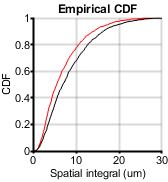

cd(defaultDir);
addpath('156_5 tecta flfl','159_7 tecta wt','165_2 tecta wt','165_3 flfl','178_5 tecta flfl','188_3 tecta flfl','188_7 flfl','190_1 tecta flfl','190_2 tecta flfl','192_1 tecta flfl','192_2 flfl','192_2 tecta flfl','198_5 tecta wt','200_1 flfl', '221_3 tecta flfl', '224_4 flfl','227_1 tecta wt','227_2 tecta wt','227_3 tecta wt','227_4 tecta wt','228_1 flfl','233_1 flfl','233_2 tecta flfl','233_3 flfl','245_1 flfl','246_1 tecta wt','246_2 tecta wt','262_1 flfl');
scale = 7.6777; % microns perpixel
cx1 = load('spatialAnalysis165_3.mat');
cx2 = load('spatialAnalysis188_7.mat');
cx3 = load('spatialAnalysis192_2.mat');
cx4 = load('spatialAnalysis224_4.mat');
cx5 = load('spatialAnalysis245_1.mat');
cx6 = load('spatialAnalysis262_1.mat');
cx7 = load('spatialAnalysis233_1.mat');

tectacx1 = load('spatialAnalysis156_5.mat');
tectacx2 = load('spatialAnalysis178_5.mat');
tectacx3 = load('spatialAnalysis188_3.mat');
tectacx4 = load('spatialAnalysis190_1.mat');
tectacx5 = load('spatialAnalysis190_2.mat');
tectacx6 = load('spatialAnalysis192_1.mat');
tectacx7 = load('spatialAnalysis221_3.mat');
tectacx8 = load('spatialAnalysis233_2.mat');

cxInt = [cx1.eventStats.integral,cx2.eventStats.integral,cx3.eventStats.integral,cx4.eventStats.integral,cx5.eventStats.integral,cx6.eventStats.integral,cx7.eventStats.integral];
tectacxInt = [tectacx1.eventStats.integral,tectacx2.eventStats.integral,tectacx3.eventStats.integral,tectacx4.eventStats.integral,tectacx5.eventStats.integral,tectacx6.eventStats.integral,tectacx7.eventStats.integral,tectacx8.eventStats.integral,];

figure
h1 = cdfplot(tectacxInt);
hold on
h2 = cdfplot(cxInt);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Spatial integral (um)');
ylabel('CDF');
xlim([0 30])
xticks([0 10 20 30])
figQuality(gcf,gca,[1.75 1.9])

[h p] = kstest2(cxInt,tectacxInt);
 p

p = 1.0825e-09

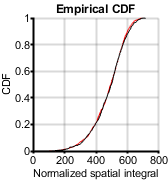

 
cxIntNorm = [cx1.eventStats.integralnorm,cx2.eventStats.integralnorm,cx3.eventStats.integralnorm,cx4.eventStats.integralnorm,cx5.eventStats.integralnorm,cx6.eventStats.integralnorm,cx7.eventStats.integralnorm]*scale;
tectacxIntNorm = [tectacx1.eventStats.integralnorm,tectacx2.eventStats.integralnorm,tectacx3.eventStats.integralnorm,tectacx4.eventStats.integralnorm,tectacx5.eventStats.integralnorm,tectacx6.eventStats.integralnorm,tectacx7.eventStats.integralnorm,tectacx8.eventStats.integralnorm,]*scale;

 
 figure
h1 = cdfplot(tectacxIntNorm);
hold on
h2 = cdfplot(cxIntNorm);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Normalized spatial integral');
ylabel('CDF');
xlim([0 800])
xticks([0 200 400 600 800])
figQuality(gcf,gca,[1.75 1.9])

[h p] = kstest2(cxIntNorm,tectacxIntNorm);
 p

p = 0.6577


 % mean spatial integral
 cxBWmean = [mean([cx1.eventStats.integralnorm]),mean([cx2.eventStats.integralnorm]),mean([cx3.eventStats.integralnorm]),mean([cx4.eventStats.integralnorm]),mean([cx5.eventStats.integralnorm]),mean([cx6.eventStats.integralnorm])]*scale;
 tectacxBWmean = [mean([tectacx1.eventStats.integralnorm]),mean([tectacx2.eventStats.integralnorm]),mean([tectacx3.eventStats.integralnorm]),mean([tectacx4.eventStats.integralnorm]),mean([tectacx5.eventStats.integralnorm]),mean([tectacx6.eventStats.integralnorm]),mean([tectacx7.eventStats.integralnorm]),mean([tectacx8.eventStats.integralnorm])]*scale;
 
 conditions2 = {'Con','cKO'};
dim = [1 2];
ylbl1 = 'Mean band width (um)';
[fig1 h p1] = compare2(cxBWmean,tectacxBWmean,conditions2,ylbl1,dim);

not normal
    0.4908

   0



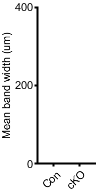

ylim([0 400])
yticks([0 200 400])

p1

p1 = 0.4908

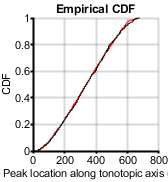


 
 % locations of events
cxLoc = [cx1.eventStats.xloc,cx2.eventStats.xloc,cx3.eventStats.xloc,cx4.eventStats.xloc,cx5.eventStats.xloc,cx6.eventStats.xloc,cx7.eventStats.xloc]*scale-50;
tectacxLoc = [tectacx1.eventStats.xloc,tectacx2.eventStats.xloc,tectacx3.eventStats.xloc,tectacx4.eventStats.xloc,tectacx5.eventStats.xloc,tectacx6.eventStats.xloc,tectacx7.eventStats.xloc,tectacx8.eventStats.xloc,]*scale-50;

 figure
h1 = cdfplot(tectacxLoc);
hold on
h2 = cdfplot(cxLoc);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Peak location along tonotopic axis (um)');
ylabel('CDF');
xlim([0 800])
xticks([0 200 400 600 800])
figQuality(gcf,gca,[1.75 1.9])

 
 [h p] = kstest2(tectacxLoc,cxLoc);
 p

p = 0.9358

% band width

perctile = 0.75;
scale = 7.6777; % microns perpixel
% calculate BW of all normalized events 
cx1BW = getSpatialBW(cx1,perctile);
cx2BW = getSpatialBW(cx2,perctile);
cx3BW = getSpatialBW(cx3,perctile);
cx4BW = getSpatialBW(cx4,perctile);
cx5BW = getSpatialBW(cx5,perctile);
cx6BW = getSpatialBW(cx6,perctile);
cx7BW = getSpatialBW(cx7,perctile);

cxBW = [cx1BW,cx2BW, cx3BW, cx4BW, cx5BW, cx6BW, cx7BW]*scale;
size(cxBW )

ans =            1        1290


tectacx1BW = getSpatialBW(tectacx1,perctile);
tectacx2BW = getSpatialBW(tectacx2,perctile);
tectacx3BW = getSpatialBW(tectacx3,perctile);
tectacx4BW = getSpatialBW(tectacx4,perctile);
tectacx5BW = getSpatialBW(tectacx5,perctile);
tectacx6BW = getSpatialBW(tectacx6,perctile);
tectacx7BW = getSpatialBW(tectacx7,perctile);
tectacx8BW = getSpatialBW(tectacx8,perctile);

 tectacxBW = [tectacx1BW,tectacx2BW,tectacx3BW,tectacx4BW,tectacx5BW,tectacx6BW,tectacx7BW,tectacx8BW]*scale;
 size(tectacxBW)

ans =            1        1385


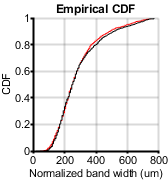

 figure
h1 = cdfplot(tectacxBW);
hold on
h2 = cdfplot(cxBW);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Normalized band width (um)');
ylabel('CDF');
xlim([0 800])
xticks([0 200 400 600 800])
figQuality(gcf,gca,[1.75 1.9])

[h p] = kstest2(tectacxBW,cxBW);
 p

p = 0.4756

 
  % mean bandwidth by animal
 cxBWmean = [mean(cx1BW),mean(cx2BW),mean(cx3BW),mean(cx4BW),mean(cx5BW),mean(cx6BW),mean(cx7BW)]*scale;
 tectacxBWmean = [mean(tectacx1BW),mean(tectacx2BW),mean(tectacx3BW),mean(tectacx4BW),mean(tectacx5BW),mean(tectacx6BW),mean(tectacx7BW),mean(tectacx8BW)]*scale;
 
 conditions2 = {'Con','cKO'};
dim = [1 2];
ylbl1 = 'Mean band width (um)';
[fig1 h p1] = compare2(cxBWmean,tectacxBWmean,conditions2,ylbl1,dim);

not normal
    0.9551

   0



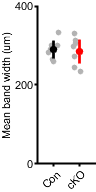

ylim([0 400])
yticks([0 200 400])

p1

p1 = 0.9551


%% 
perctile = 0.75;
scale = 7.6777; % microns perpixel
% calculate BW of all normalized events 
cx1BW = getSpatialBWCentral(cx1,perctile);
cx2BW = getSpatialBWCentral(cx2,perctile);
cx3BW = getSpatialBWCentral(cx3,perctile);
cx4BW = getSpatialBWCentral(cx4,perctile);
cx5BW = getSpatialBWCentral(cx5,perctile);
cx6BW = getSpatialBWCentral(cx6,perctile);
cx7BW = getSpatialBWCentral(cx7,perctile);

cxBW = [cx1BW,cx2BW, cx3BW, cx4BW, cx5BW, cx6BW, cx7BW]*scale;
size(cxBW )

ans =      1   375


tectacx1BW = getSpatialBWCentral(tectacx1,perctile);
tectacx2BW = getSpatialBWCentral(tectacx2,perctile);
tectacx3BW = getSpatialBWCentral(tectacx3,perctile);
tectacx4BW = getSpatialBWCentral(tectacx4,perctile);
tectacx5BW = getSpatialBWCentral(tectacx5,perctile);
tectacx6BW = getSpatialBWCentral(tectacx6,perctile);
tectacx7BW = getSpatialBWCentral(tectacx7,perctile);
tectacx8BW = getSpatialBWCentral(tectacx8,perctile);

 tectacxBW = [tectacx1BW,tectacx2BW,tectacx3BW,tectacx4BW,tectacx5BW,tectacx6BW,tectacx7BW,tectacx8BW]*scale;
 size(tectacxBW)

ans =      1   389


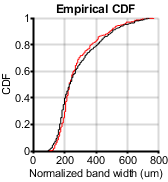

 figure
h1 = cdfplot(tectacxBW);
hold on
h2 = cdfplot(cxBW);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Normalized band width (um)');
ylabel('CDF');
xlim([0 800])
xticks([0 200 400 600 800])
figQuality(gcf,gca,[1.75 1.9])

[h p] = kstest2(tectacxBW,cxBW);
 p

p = 0.0358

 
 cxBWmean = [mean(cx1BW),mean(cx2BW),mean(cx3BW),mean(cx4BW),mean(cx5BW),mean(cx6BW)]*scale;
 tectacxBWmean = [mean(tectacx1BW),mean(tectacx2BW),mean(tectacx3BW),mean(tectacx4BW),mean(tectacx5BW),mean(tectacx6BW),mean(tectacx7BW),mean(tectacx8BW)]*scale;
 
 conditions2 = {'Control','Cx26 cKO'};
dim = [1 1.8];
ylbl1 = 'Mean band width (um)';
[fig1 h p1] = compare2(cxBWmean,tectacxBWmean,conditions2,ylbl1,dim);

not normal
    0.6620

   0



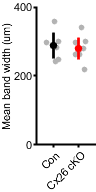

ylim([0 400])
yticks([0 200 400])

p1

p1 = 0.6620


subP = handleTheSubplot({fig1,fig1,fig1},[1 3]);
figQuality(subP,gca,[3 2])

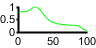

% example profiles - control and cKO

 figure
  plot(cx5.smRIC(:,913)./max(cx5.smRIC(:,913)),'g')
  ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

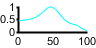

 
figure
  plot(cx5.smRIC(:,1092)./max(cx5.smRIC(:,1092)),'c')
   ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

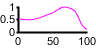

 
 figure
    plot(cx5.smRIC(:,1480)./max(cx5.smRIC(:,1480)),'m')
     ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

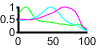

 
  figure  
 plot(cx5.smRIC(:,1283)./max(cx5.smRIC(:,1283)),'g')
 hold on
 % plot(tmem4.smRIC(:,1024)./max(tmem4.smRIC(:,1024)),'g')
 plot(cx5.smRIC(:,1092)./max(cx5.smRIC(:,1092)),'c')
  plot(cx5.smRIC(:,1480)./max(cx5.smRIC(:,1480)),'m')
 ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

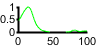

  figure
  plot(tectacx4.smRIC(:,558)./max(tectacx4.smRIC(:,558)),'g')
  ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

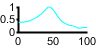

 
figure
  plot(tectacx4.smRIC(:,1009)./max(tectacx4.smRIC(:,1009)),'c')
   ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

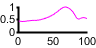

 
 figure
    plot(tectacx4.smRIC(:,1602)./max(tectacx4.smRIC(:,1602)),'m')
     ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

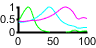

 
  figure  
 plot(tectacx4.smRIC(:,558)./max(tectacx4.smRIC(:,558)),'g')
 hold on
 % plot(tectacx4.smRIC(:,1024)./max(tectacx4.smRIC(:,1024)),'g')
 plot(tectacx4.smRIC(:,1009)./max(tectacx4.smRIC(:,1009)),'c')
  plot(tectacx4.smRIC(:,1602)./max(tectacx4.smRIC(:,1602)),'m')
 ylim([0 1])
 figQuality(gcf,gca,[1 0.5])